# Método de Bisección

**Autor(a): Francisco Javier Ramírez Arias, Profesor-Investigador de Tiempo Completo: Universidad Autónoma de Baja California: (FCITEC-Valle de las Palmas)**

## Resumen

*Esta actividad presenta el Método de Bisección como técnica numérica para encontrar raíces de funciones de una variable. Incluye conceptos clave como tolerancia, error absoluto, error relativo y el Teorema del Valor Intermedio, además de distintas versiones del algoritmo ilustradas con ejemplos en MATLAB. Se muestra una aplicación en ingeniería, lo que permite desarrollar habilidades analíticas, computacionales y prácticas en métodos numéricos.*

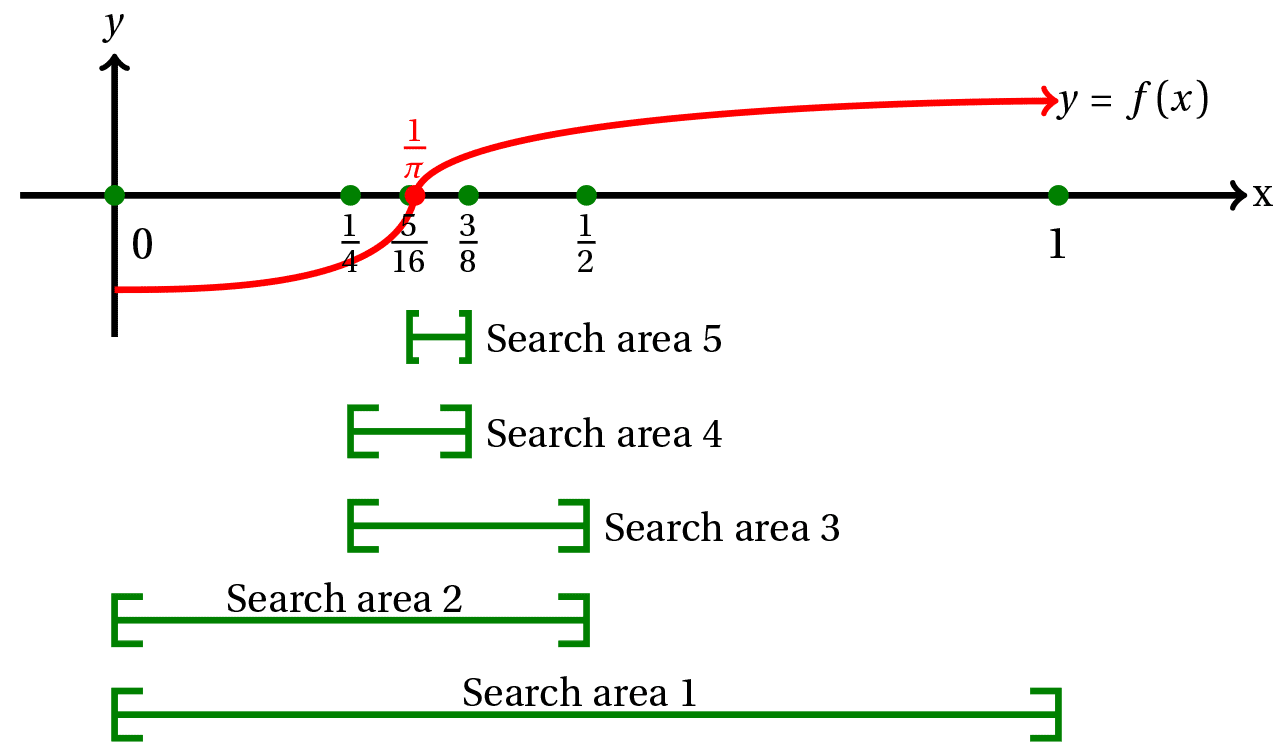

## Objetivos de Aprendizaje

### *Conceptos que deben aprender*

- *Comprender la ****idea de raíz de una función**** en ecuaciones de una variable.*

- *Entender el ****Teorema del Valor Intermedio**** como fundamento teórico del método.*

- *Reconocer el método de bisección como un**** método iterativo de búsqueda de raíces****.*

- *Identificar los**** criterios de paro**** más comunes.*

### *Contenidos que se deben asimilar*

- *Fundamendo matemático y ecuaciones asociadas el método de bisección.*

- *Procedimiento paso a paso para aplicar el método.*

- *Ejemplos analíticos y numéricos que muestren el proceso de aproximación.*

- *Uso de MATLAB como herramienta de programación para implementar el algoritmo.*

- *Aplicaciones del método en problemas reales de ingeniería y en la vida cotidiana.*

### *Habilidades que deben desarrollar*

#### *Analíticas y matemáticas:*

- *Plantear una función y reconocer intervalor que contengan raíces.*

- *Realizar cálculos iterativos manuales para aproximar soluciones.*

- *Interpretar gráficas de funciones y la localización de las raíces.*

#### *Computacionales:*

- *Implementar el método en MATLAB.*

- *Verificar los resultados manuales con resultados computacioales.*

- *Analizar la influencia de la tolerancia en la precisión del método*

#### *De la aplicación práctica*

- *Modelar problemas de ingeniería y de la vida real como ecuaciones de una variable.*

- *Seleccionar el intervalo adecuado para aplicar el método.*

- *relacionar la teoría con fenómenos físicos. *

## Antes de empezar 

En muchas áreas de la ingeniería y las ciencias es común encontrar ecuaciones no lineales que no pueden resolverse de forma algebraica. Es esos casos, se recurre a los métodos numéricos para aproximarse a sus soluciones. El método de bisección es uno de los algoritmos más sencillos y robustos para encontrar raices de una ecuación de una variable. Se basa en el Teorema del Valor Intermedio, que garantiza la existencia de una raíz dentro de un intervalo si la función cambia de signo en ese intervalo.

### Fundamento Matemáticos

El método de bisección se basa en el Teorema del Valor Intermedio, en el cual establece que;  si $f$ es una funcion continua en $\left\lbrack a,b\right\rbrack$ y$f\left(a\right)*f\left(b\right)<0$, entonces existe al menos un $c\in \left(a,b\right)$ tal que $f\left(c\right)=0$.

### Algoritmo del Método de Bisección

1._Seleccionar $a$ y $b$ tales que $f\left(a\right)*f\left(b\right)<0\ldotp$

2._Calcular el punto medio $c=\frac{a+b}{2}$.

3._Evaluar $f\left(c\right)$:

               
$$\[
\text{Si } f(c) = 0, \quad \text{entonces } c \text{ es la raíz.}
\]

\[
\text{Si } f(a)\cdot f(c) < 0, \quad \text{la raíz está en } [a,c].
\]

\[
\text{Si } f(c)\cdot f(b) < 0, \quad \text{la raíz está en } [c,b].
\]
$$


4._Repetir el proceso hasta que $\left|b-a\right|<\textrm{tolerancia}$

### Criterio de parada

- **Tolerancia:** $\left(\epsilon \right)$ es el error máximo aceptable que fijamos de antemano para detener un proceso numérico. Indica "que tan cerca" queremos estar de la solución antes de parar. Es un umbral practico: cuando el error estimado cae por debajo de $\epsilon$, consideramos suficiente la aproximación.

- **Error absoluto**: es la medida de la diferencia entre un valor exacto (o real ) y un valor aproximado (o medido). Es el criterio principal y por defecto del método de bisección. El algoritmo se detiene cuando el ancho del intervalo que contiene a la raiz es menor a una tolerancia especificada. Define de la siguiente manera: $\left|b-a\right|<\epsilon$ o equivalente $\frac{b-a}{2}<\epsilon$.

- **Error relativo: **se define como la relación entre el tamaño del intervalo actual y el valor absoluto de la aproximación actual. El error relativo mide la precision de la aproximación en términos porcentuales respecto al vaor estimado. El algoritmos se detiene cuando el error relativo es menor que una tolerancia especificada $\epsilon$. El error relativo se define de la siguiente manera: $\frac{\left|b_n -a_n \right|}{\left|c_n \right|}<\epsilon$.

- **Número máximo de iteraciones: **es un límite preestablecido de repeticiones que se en un algoritmo iterativo. su función es evitar que el método se ejecute indefinidamente en caso de que no se cumpla el criterio de paro (por ejemplo, alcanzar la tolerancia). En el método de bisección, este parámetro garantiza que el proceso finalice aun si la raíz no se ha aproximado con la precisión deseada, ofreciendo un control de seguridad y un balance entre tiempo de cómputo y nivel de exactitud.

## Sección 1: Conceptos Básicos

### 1.1 Raíces de una Función

Una raíz (o cero) de una función $f\left(x\right)$ es un valor $r$ tal que: $f\left(r\right)=0$. Graficamente, una raíz corresponde al punto donde la curva de la función corta o toca el eje X.

Ejemplos:

- La función $f\left(x\right)=x-3$ tiene una raíz en $x=3\ldotp$

- La función $f\left(x\right)=x^2 -4$ tiene una raíces en en $x=-2$ y $x=2$.

- La función $f\left(x\right)={\left(x-1\right)}^2$ tiene una raíz doble en $x=1$, donde "toca" el eje X pero no lo cruza.

% Raíz de una función: concepto básico

% Función  f(x)=x^2-4
f = @(x) x.^2 - 4;

% Definir un rango de valores para x
x = linspace(-5,5,400);
y=f(x);

% Raíces de la función
raices = [-2 , 2]

raices =     -2     2


valores_raices = f(raices)

valores_raices =      0     0


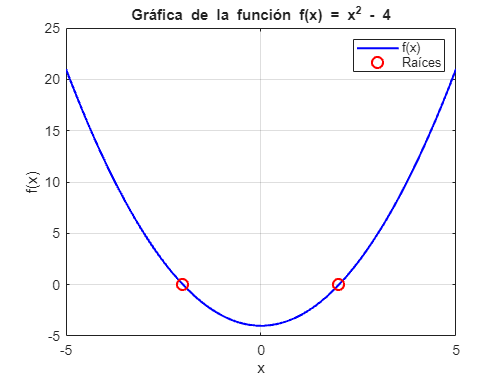


% Graficar la función
figure;
plot(x, y, 'b', 'LineWidth',1.5);
hold on;

% Calcular las raíces de la función
plot(raices, valores_raices, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);

%Etiquetas y título 
xlabel('x');
ylabel('f(x)');
title('Gráfica de la función f(x) = x^2 - 4');
legend('f(x)', 'Raíces');
grid on;
hold off;

% Verificación numérica de las raíces de la función
fprintf('f(-2) = %.1f\n', f(-2));

f(-2) = 0.0


fprintf('f( 2) = %.1f\n', f( 2));

f( 2) = 0.0


### *¿Qué nos enseña este código?*

- Muestra cada iteración, el intervalo de $a$ y $b$ y la longitud del intervalo $\left|b-a\right|$.

- Se puede observar como el intervalo se reduce en cada paso.

- El programa se detiene automaticamente al cumplirse:$\left|b-a\right|<\epsilon$

### 1.2 Tolerancia

**Tolerancia:** $\left(\epsilon \right)$ es el error máximo aceptable que fijamos de antemano para detener un proceso numérico. Indica "que tan cerca" queremos estar de la solución antes de parar. Es un umbral practico: cuando el error estimado cae por debajo de $\epsilon$, consideramos suficiente la aproximación.

%Concepto de Tolerancia

tol = str2double("0.01");     %Umbral de error permitido

error =     2.61;     %Error inicial
iter = 0;                                    %Iteraciones

while error > tol
    iter = iter + 1;                                    %Iteraciones
    error = error/2;                                    %Reducción del error
    fprintf('Iteración %d: error = %.4f\n',iter, error) %Impresion de variables
end

Iteración 1: error = 1.3050
Iteración 2: error = 0.6525
Iteración 3: error = 0.3262
Iteración 4: error = 0.1631
Iteración 5: error = 0.0816
Iteración 6: error = 0.0408
Iteración 7: error = 0.0204
Iteración 8: error = 0.0102
Iteración 9: error = 0.0051



%Resultado final de las iteraciones
fprintf('\nSe detuvo porque el error < tol = %.2f\n', tol);


Se detuvo porque el error < tol = 0.01


### Que ilustra el código anterior

- Define $\epsilon$ como tolerancia de aporte aporte marginal.

- El "error" se va reduciendo en cada iteración

- Paramos cuando el siguiente aporte ya es "insignificante" $\left(<\epsilon \right)$.

- El ciclo se detiene automaticamente cuando el error es menor que la tolerancia.

- El concepto de tolerancia es un umbral que decide cuándo detenerse porque el error adicional esperado es menor que lo aceptable.

### Explicación Gráfica

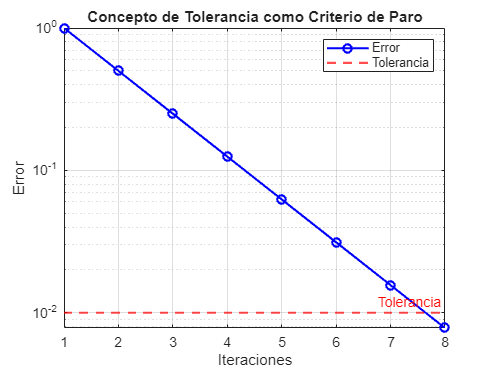

%% Concepto de tolerancia con gráfica
clc; clear;

% Definir tolerancia
tol = 0.01;   

% Simulación de error decreciente
error = 1;
errors = [];
iters = 0;

while error > tol
    iters = iters + 1;
    errors(iters) = error; %#ok<SAGROW>
    error = error / 2;  % Reducimos el error artificialmente
end

% Guardar el último error
iters = iters + 1;
errors(iters) = error;

% Crear vector de iteraciones
x = 1:iters;

% Graficar
figure;
semilogy(x, errors, 'o-b','LineWidth',1.5); hold on; % Escala log en eje Y
yline(tol,'--r','Tolerancia','LineWidth',1.5);

grid on;
xlabel('Iteraciones');
ylabel('Error');
title('Concepto de Tolerancia como Criterio de Paro');
legend('Error','Tolerancia','Location','northeast');

### Que nos enseña esta gráfica

- Cómo disminuye el error.

- Se detiene cuando el error cae por debajo de la tolerancia.

- La linea azul muestra como disminuye el error.

- La linea roja marca el criterio de paro.

### 1.3 Criterios de Paro: Error Absoluto

**Error absoluto**: es la medida de la diferencia entre un valor exacto (o real ) y un valor aproximado (o medido). Se define de la siguiente manera: $\left|b-a\right|<\epsilon$ o equivalente $\frac{b-a}{2}<\epsilon$.

%% Exploración del Criterio de Paro: Error Absoluto

% Imagina que tenemos un intervalo inicial
a = 1; 
b = 2;

% Definimos una tolerancia
tol = 0.01;

% Mostramos la idea del criterio de paro
fprintf('Intervalo inicial: [%.2f, %.2f]\n', a, b);

Intervalo inicial: [1.00, 2.00]


fprintf('Longitud inicial del intervalo: %.2f\n\n', b-a);

Longitud inicial del intervalo: 1.00




% Reducimos artificialmente el intervalo en cada paso (simulación)
for k = 1:10
    % Reducimos el intervalo a la mitad (solo para ilustrar)
    b = (a+b)/2;
    error = abs(b - a);   % Longitud actual del intervalo
    
    fprintf('Iter %d: Intervalo = [%.4f, %.4f], Error = %.4f\n', k, a, b, error);
    
    % Aquí aparece el concepto de criterio de paro
    if error < tol
        fprintf('\nSe cumple el criterio de paro: |b-a| < %.4f\n', tol);
        break;
    end
end

Iter 1: Intervalo = [1.0000, 1.5000], Error = 0.5000
Iter 2: Intervalo = [1.0000, 1.2500], Error = 0.2500
Iter 3: Intervalo = [1.0000, 1.1250], Error = 0.1250
Iter 4: Intervalo = [1.0000, 1.0625], Error = 0.0625
Iter 5: Intervalo = [1.0000, 1.0312], Error = 0.0312
Iter 6: Intervalo = [1.0000, 1.0156], Error = 0.0156
Iter 7: Intervalo = [1.0000, 1.0078], Error = 0.0078



Se cumple el criterio de paro: |b-a| < 0.0100


### Que nos enseña este codigo

- Muestra cada iteración, el intervalo de $a$ y $b$ y la longitud del intervalo $\left|b-a\right|$.

- Se puede observar como el intervalo se reduce en cada paso.

- El programa se detiene automaticamente al cumplirse:$\left|b-a\right|<\epsilon$

### 1.4 Criterios de Paro: Error Relativo

 El algoritmos se detiene cuando el error relativo es menor que una tolerancia especificada $\epsilon$. El error relativo se define de la siguiente manera: $\frac{\left|b_n -a_n \right|}{\left|c_n \right|}<\epsilon$.

%% Exploración del Criterio de Paro: Error Relativo

% Imagina que tenemos un intervalo inicial
a = 1; 
b = 2;

% Definimos una tolerancia
tol = 0.01;

% Mostramos la idea del criterio de paro
fprintf('Intervalo inicial: [%.2f, %.2f]\n', a, b);

Intervalo inicial: [1.00, 2.00]


fprintf('Longitud inicial del intervalo: %.2f\n\n', b-a);

Longitud inicial del intervalo: 1.00




% Reducimos artificialmente el intervalo en cada paso (simulación)
for k = 1:10
    % Calculamos el punto medio (referencia para el error relativo)
    c = (a+b)/2;
    
    % Reducimos el intervalo a la mitad (solo para ilustrar)
    b = c;
    
    % Error relativo
    error_rel = abs(b - a) / abs(c);
    
    fprintf('Iter %d: Intervalo = [%.4f, %.4f], Error Relativo = %.4f\n', ...
        k, a, b, error_rel);
    
    % Aquí aparece el concepto de criterio de paro relativo
    if error_rel < tol
        fprintf('\nSe cumple el criterio de paro relativo: |b-a|/|c| < %.4f\n', tol);
        break;
    end
end

Iter 1: Intervalo = [1.0000, 1.5000], Error Relativo = 0.3333
Iter 2: Intervalo = [1.0000, 1.2500], Error Relativo = 0.2000
Iter 3: Intervalo = [1.0000, 1.1250], Error Relativo = 0.1111
Iter 4: Intervalo = [1.0000, 1.0625], Error Relativo = 0.0588
Iter 5: Intervalo = [1.0000, 1.0312], Error Relativo = 0.0303
Iter 6: Intervalo = [1.0000, 1.0156], Error Relativo = 0.0154
Iter 7: Intervalo = [1.0000, 1.0078], Error Relativo = 0.0078



Se cumple el criterio de paro relativo: |b-a|/|c| < 0.0100


### *¿Qué nos enseña este código?*

- El concepto de criterio de paro de error relativo.

- Evolución del error, se puede ver cómo el error relativo disminuye paso a paso hasta que se cumple la condición de paro.

- Una forma sencilla, para que los estudiantes entiendan primero qué significa parar un cálculo por tolerancia.

- Un mensaje para los esudiantes para comprender la diferencia entre error absoluto y relativo. 

## Sección 2: Teorema del Valor Intermedio

El método de bisección se basa en el Teorema del Valor Intermedio, en el cual establece que;  si $f$ es una funcion continua en $\left\lbrack a,b\right\rbrack$ y$f\left(a\right)*f\left(b\right)<0$, entonces existe al menos un $c\in \left(a,b\right)$ tal que $f\left(c\right)=0$.

%Función a evaluar para observar si es aplicable el Teorema del Valor
%intermedio
f = @(x) x.^2 - 4;

%Definimos el intervalo [a,b]
%En este caso, una de las raíces se encuentra
%en x=-2
a = 1; % Límite inferior del intervalo
b = 3; % Límite superior del intervalo

%Se evalua la función en los extremos del intervalo.
fa = f(a);
fb = f(b);

%Se impremen los resultados.
fprintf('Evaluando la función en el intervalo [%.2f, %.2f]\n', a, b);

Evaluando la función en el intervalo [1.00, 3.00]


fprintf('f(%.2f) = %.2f\n', a, fa);

f(1.00) = -3.00


fprintf('f(%.2f) = %.2f\n', b, fb);

f(3.00) = 5.00



% Condición del Teorema del Valor Intermedio
% Si f(a) y f(b) tienen signos opuestos, su producto es negativo.
if fa * fb < 0
    fprintf('\nEl producto f(a) * f(b) es negativo (%.2f). \n', fa * fb);
    fprintf('✅ La funcion cambia de signo en el intervalo. Por el Teorema del Valor Intermedio, una raiz existe en [%.2f, %.2f].\n', a, b);
else
    fprintf('\nEl producto f(a) * f(b) es positivo o cero (%.2f). \n', fa * fb);
    fprintf('❌ El Teorema del Valor Intermedio no garantiza la existencia de una raiz en este intervalo.\n');
end


El producto f(a) * f(b) es negativo (-15.00). 


✅ La funcion cambia de signo en el intervalo. Por el Teorema del Valor Intermedio, una raiz existe en [1.00, 3.00].


### *¿Qué nos enseña este código?*

- La aplicación de cambio de signo, lo que implica que la función cruza el eje X dentro del intervalo utilizado.

- Aplicación del Teorema de Valor Intermedio, el código verifica esta condición y concluye que, al haber un cambio de signo, existe al menos una raíz en el intervalo.

## Sección 3: Algoritmo de Bisección

### 3.1 Algoritmo de Bisección (Iterativo; sin criterio de interrupción)

Problema: Encontrar la raíz de la ecuación $f\left(x\right)=x^2 -4$ en el intervalo $\left\lbrack 1\ldotp 5,3\right\rbrack$.

**Paso 1: Verificar el intervalo.**

- 
$$f\left(1\ldotp 5\right)={\left(1\ldotp 5\right)}^2 -4=2\ldotp 25-4=-1\ldotp 75$$


- 
$$f\left(3\right)={\left(3\right)}^2 -4=5$$


- 
$$f\left(1\ldotp 5\right)*f\left(3\right)=\left(-1\ldotp 75\right)*\left(5\right)=-8\ldotp 75<0$$


**El Teorema Aplica**

**Paso 2: Iteraciones numericas.**

**Iteracion 1:**

- Intervalo: $\left\lbrack a_1 ,b_1 \right\rbrack =\left\lbrack 1\ldotp 5,3\right\rbrack$

- Punto medio $p_1 =\frac{1\ldotp 5+3}{2}=2\ldotp 25$

- Evaluacion: $f\left(2\ldotp 25\right)={\left(2\ldotp 25\right)}^2 -4=5\ldotp 0625-4=1\ldotp 0625$

- Decision:

-     
$$f\left(1\ldotp 5\right)*f\left(2\ldotp 25\right)=\left(-1\ldotp 75\right)*\left(1\ldotp 0625\right)<0$$


-     El nuevo intervalo es $\left\lbrack 1\ldotp 5,2\ldotp 25\right\rbrack$

**Iteracion 2:**

- Intervalo: $\left\lbrack a_2 ,b_2 \right\rbrack =\left\lbrack 1\ldotp 5,2\ldotp 25\right\rbrack$

- Punto medio $p_2 =\frac{1\ldotp 5+2\ldotp 25}{2}=1\ldotp 875$

- Evaluacion: $f\left(1\ldotp 875\right)={\left(1\ldotp 875\right)}^2 -4=3\ldotp 515625-4=-0\ldotp 484375$

- Decision:

-     
$$f\left(1\ldotp 875\right)*f\left(2\ldotp 25\right)=\left(-0\ldotp 484375\right)*\left(1\ldotp 0625\right)<0$$


-     El nuevo intervalo es $\left\lbrack 1\ldotp 875,2\ldotp 25\right\rbrack$

**Iteracion 3:**

- Intervalo: $\left\lbrack a_3 ,b_3 \right\rbrack =\left\lbrack 1\ldotp 875,2\ldotp 25\right\rbrack$

- Punto medio $p_1 =\frac{1\ldotp 875+2\ldotp 25}{2}=2\ldotp 0625$

- Evaluacion: $f\left(2\ldotp 0625\right)={\left(2\ldotp 0625\right)}^2 -4=4\ldotp 25390625-4=0\ldotp 25390625$

- Decision:

-     
$$f\left(1\ldotp 875\right)*f\left(2\ldotp 0625\right)=\left(-0\ldotp 484375\right)*\left(0\ldotp 25390625\right)<0$$


-     El nuevo intervalo es $\left\lbrack 1\ldotp 875,\;2\ldotp 0625\right\rbrack$

El proceso continua, y la aproximación se vuelve cada vez más precisa, acercándose a la raíz real $x=2\ldotp$


% Celda para adicionar código
% Script de MATLAB para el ejemplo analítico del método de bisección
% Función: f(x) = x^2 - 4

% 1. Definir la función
f = @(x) x.^2 - 4;

% 2. Definir los parámetros iniciales
a = 1.5;         % Límite inferior del intervalo
b = 3;           % Límite superior del intervalo

% Número máximo de iteraciones (criterio de parada)

max_iter =5;

% 3. Verificar el teorema del valor intermedio
fa = f(a);
fb = f(b);
if fa * fb >= 0
    error('La función no cambia de signo en el intervalo dado. Elija un nuevo intervalo.');
end

% 4. Mostrar el encabezado de la tabla de resultados
fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('Iter |     a     |     b     |     p     |   f(p)    |\n');

Iter |     a     |     b     |     p     |   f(p)    |


fprintf('------------------------------------------------------\n');

------------------------------------------------------



% 5. Bucle principal del método de bisección
for k = 1:max_iter
    
    % Calcular el punto medio
    p = (a + b) / 2;
    fp = f(p);
    
    % Imprimir los resultados de la iteración actual
    fprintf('%4d | %.5f | %.5f | %.5f | %.5f |\n', k, a, b, p, fp);
    
    % Verificar si se ha encontrado la raíz exacta (poco probable)
    if fp == 0
        fprintf('------------------------------------------------------\n');
        fprintf('Raiz exacta encontrada en p = %.5f en la iteracion %d.\n', p, k);
        return; % Salir del script
    end
    
    % Acotar el nuevo intervalo
    if f(a) * fp < 0
        b = p;  % La raíz está en la mitad izquierda del intervalo
    else
        a = p;  % La raíz está en la mitad derecha del intervalo
    end
end

   1 | 1.50000 | 3.00000 | 2.25000 | 1.06250 |
   2 | 1.50000 | 2.25000 | 1.87500 | -0.48438 |
   3 | 1.87500 | 2.25000 | 2.06250 | 0.25391 |
   4 | 1.87500 | 2.06250 | 1.96875 | -0.12402 |
   5 | 1.96875 | 2.06250 | 2.01562 | 0.06274 |



% 6. Mostrar el resultado final después de todas las iteraciones
fprintf('------------------------------------------------------\n');

------------------------------------------------------


fprintf('Aproximación de la raiz después de %d iteraciones: p = %.5f\n', max_iter, p);

Aproximación de la raiz después de 5 iteraciones: p = 2.01562


### *¿Qué nos enseña este código?*

- Los diferentes fundaamentos teóricos aplicados.

- El procedimiento iterativo del método de bisección.

- Resultados paso a paso.

- Número máximo de iteraciones.

- Resultado final, que nos muestra la aproximación de la raíz.

### 3.2 Algoritmo de Bisección (Completo)

Problema: Encontrar la raíz de la ecuación $f\left(x\right)=x^2 -4$ en el intervalo $\left\lbrack 1\ldotp 5,3\right\rbrack$.

% Script de MATLAB para el ejemplo analítico del método de bisección
% Función: f(x) = x^2 - 4

% 1. Definir la función
f = @(x) x.^2 - 4;

% 2. Definir los parámetros iniciales
a = 1.5;         % Límite inferior del intervalo
b = 3;           % Límite superior del intervalo

% Número máximo de iteraciones (criterio de seguridad)
max_iter = 50;

% ÚNICA tolerancia (criterio de paro por tamaño de intervalo)
tol = 1e-6;   

% 3. Verificar el Teorema del Valor Intermedio
fa = f(a);
fb = f(b);
if fa * fb >= 0
    error('La función no cambia de signo en el intervalo dado. Elija un nuevo intervalo.');
end

% 4. Mostrar el encabezado de la tabla de resultados
fprintf('---------------------------------------------------------------\n');

---------------------------------------------------------------


fprintf('Iter |     a     |     b     |     p     |    f(p)    \n');

Iter |     a     |     b     |     p     |    f(p)    


fprintf('---------------------------------------------------------------\n');

---------------------------------------------------------------



% 5. Bucle principal del método de bisección
for k = 1:max_iter
    % Punto medio y evaluación
    p  = (a + b)/2;
    fp = f(p);

    % Imprimir la iteración actual
    fprintf('%4d | %.5f | %.5f | %.5f | %.5e \n', k, a, b, p, fp);

    % ---- CRITERIO DE PARO ----
    if abs(b - a) < tol
        fprintf('---------------------------------------------------------------\n');
        fprintf('Criterio de paro alcanzado en iter %d: |b-a| < %.1e\n', k, tol);
        fprintf('Raíz aproximada: p = %.8f\n', p);
        return;
    end

    % Actualizar intervalo usando el signo
    if fa * fp < 0
        b  = p;     % raíz en [a, p]
        fb = fp;
    else
        a  = p;     % raíz en [p, b]
        fa = fp;
    end
end

   1 | 1.50000 | 3.00000 | 2.25000 | 1.06250e+00 
   2 | 1.50000 | 2.25000 | 1.87500 | -4.84375e-01 
   3 | 1.87500 | 2.25000 | 2.06250 | 2.53906e-01 
   4 | 1.87500 | 2.06250 | 1.96875 | -1.24023e-01 
   5 | 1.96875 | 2.06250 | 2.01562 | 6.27441e-02 
   6 | 1.96875 | 2.01562 | 1.99219 | -3.11890e-02 
   7 | 1.99219 | 2.01562 | 2.00391 | 1.56403e-02 
   8 | 1.99219 | 2.00391 | 1.99805 | -7.80869e-03 
   9 | 1.99805 | 2.00391 | 2.00098 | 3.90720e-03 
  10 | 1.99805 | 2.00098 | 1.99951 | -1.95289e-03 
  11 | 1.99951 | 2.00098 | 2.00024 | 9.76622e-04 
  12 | 1.99951 | 2.00024 | 1.99988 | -4.88266e-04 
  13 | 1.99988 | 2.00024 | 2.00006 | 2.44144e-04 
  14 | 1.99988 | 2.00006 | 1.99997 | -1.22069e-04 
  15 | 1.99997 | 2.00006 | 2.00002 | 6.10354e-05 
  16 | 1.99997 | 2.00002 | 1.99999 | -3.05175e-05 
  17 | 1.99999 | 2.00002 | 2.00000 | 1.52588e-05 
  18 | 1.99999 | 2.00000 | 2.00000 | -7.62939e-06 
  19 | 2.00000 | 2.00000 | 2.00000 | 3.81470e-06 
  20 | 2.00000 | 2.00000 | 2.00000 | -1.9

---------------------------------------------------------------


Criterio de paro alcanzado en iter 22: |b-a| < 1.0e-06


Raíz aproximada: p = 1.99999988



% 6. Resultado si se alcanzó max_iter sin cumplir la tolerancia
fprintf('---------------------------------------------------------------\n');
fprintf('Aproximación tras %d iteraciones (sin cumplir tolerancia): p = %.8f\n', max_iter, p);


### *¿Qué nos enseña este código?*

- Los fundamento teóricos.

- Proceso iterativo del método de bisección.

- Criterio de paro con tolerancia.

- Presentación de los resultados.

- Número máximo de iteraciones como método de seguridad en caso de que no se cumpla el método de tolerancia.

### 3.3 Algoritmo de Bisección (Simplificado)

Problema: Encontrar la raíz de la ecuación $f\left(x\right)=x^2 -4$ en el intervalo $\left\lbrack 1\ldotp 5,3\right\rbrack$.

% Método de Bisección simplificado
f = @(x) x.^2 - 4;   % Función
a = 1.5; b = 3;      % Intervalo inicial
tol = 1e-6;          % Tolerancia

while (b - a) > tol
    p = (a+b)/2;     % Punto medio
    if f(a)*f(p) < 0
        b = p;       % Raíz en [a,p]
    else
        a = p;       % Raíz en [p,b]
    end
end

fprintf('Raíz aproximada: %.6f\n', (a+b)/2);


### *¿Qué nos enseña este código?*

- La esencia del método de bisección.

- Un criterio de paso simple.

- Simplicidad didáctica

- Aplicación al ejemplo $f\left(x\right)=x^2 -4$.

## Sección 4: Aplicación

**Planteamineto del problema**

En **ingeniería eléctrica**, los diodos semiconductores son componentes **no lineales** cuya relación corriente–tensión se describe con la **ecuación de Shockley**:


$$I=I_S \left(e^{\frac{V}{\eta V_T }} -1\right)$$


donde:

- $I$   = corriente por el diodo (A)

- $V$  = voltaje en el diodo (V)

- $I_S$�  = corriente de saturación inversa (A)

- $\eta$   = factor de idealidad (entre 1 y 2)

- $V_T$ = voltaje térmico ($\approx$26 mV a 300 K)

**Circuito propuesto**

Consideremos un circuito simple con:

- Una fuente de voltaje $V_S$

- Una resistencia $R$

- y un diodo en serie.

La ecuación de malla es:


$$V_S =V_R +V_D$$


donde $V_R =I*R\ldotp$ Sustituyendo el modelo del diodo:


$$V_S =I*R+\eta V_T \ln \left(\frac{I}{I_S }+1\right)$$


**Datos numericos:**

- Fuente: $V_S =5V$

- Resistencia: $R=100\Omega$

- Corriente de saturación: $I_S ={10}^{-12}$

- Factor de idealidad: $\eta =1\ldotp 7$

- Voltaje térmico: $V_T =0\ldotp 026V$

**Ecuación a resolver**

La ecuacion no lineal para la corriente $I$queda:


$$f\left(I\right)=5-100I-1\ldotp 7\cdot 0\ldotp 026\cdot \ln \left(\frac{I}{{10}^{-12} }+1\right)$$


**Solución del problema; encontrar la corriente **$I$** que satisface esta ecuación**.

%% Script para calcular la corriente en un diodo con el método de bisección

% Parámetros del circuito
Vs = 5;           % Voltaje de la fuente [V]
R = 100;          % Resistencia [ohm]
Is = 1e-12;       % Corriente de saturación inversa [A]
eta = 1.7;        % Factor de idealidad
Vt = 0.026;       % Voltaje térmico [V]

% Función a resolver: ecuación del diodo en circuito
f = @(I) Vs - R*I - eta*Vt*log(I/Is + 1);

% Intervalo inicial
a = 0;
b = 0.05;         % Intervalo en amperios
tol = 1e-6;       % Tolerancia
max_iter = 100;   % Máximo de iteraciones

% Verificar Teorema del Valor Intermedio
if f(a)*f(b) >= 0
    error('No hay cambio de signo en el intervalo. Elija otro intervalo.');
end

% Inicializar
c = (a+b)/2;

% Método de bisección
for k = 1:max_iter
    c = (a+b)/2;
    if abs(b - a) < tol || abs(f(c)) < tol
        break;
    end
    if f(a)*f(c) < 0
        b = c;
    else
        a = c;
    end
end

% Resultados
fprintf('Corriente en el diodo: %.6f A\n', c);

Corriente en el diodo: 0.039219 A


fprintf('Voltaje en el diodo: %.3f V\n', eta*Vt*log(c/Is + 1));

Voltaje en el diodo: 1.078 V


fprintf('Iteraciones realizadas: %d\n', k);

Iteraciones realizadas: 17


### *¿Qué nos enseña este código?*

- La aplicación del método de bisección en un modelo físico real.

- Uso del método de bisección para resolver una ecuacion no lineal.

- Implementación del criterio de paro.

- El script muestra los resultados prácticos.

## Recursos Adicionales

[https://en.wikipedia.org/wiki/Bisection_method](https://en.wikipedia.org/wiki/Bisection_method)

[https://www.geeksforgeeks.org/dsa/program-for-bisection-method/](https://www.geeksforgeeks.org/dsa/program-for-bisection-method/)

[https://www.mathworks.com/matlabcentral/fileexchange/80044-metodo-de-biseccion?s_tid=ta_fx_results](https://www.mathworks.com/matlabcentral/fileexchange/80044-metodo-de-biseccion?s_tid=ta_fx_results)

## Referencias 

-   Mikhailov, E. E. (2017). Programming with MATLAB for scientists: A beginner's introduction. CRC Press, Taylor & Francis Group.

- Chapra, S. C. (2012). *Applied numerical methods with MATLAB for engineers and scientists* (3. ed., internat. ed). McGraw-Hill.

- Gilat, A., & Subramaniam, V. (2014). *Numerical methods for engineers and scientists: An introduction with applications using matlab* (3. ed). Wiley.

- Kiusalaas, J. (2005). *Numerical methods in engineering with MATLAB*. Cambridge University Press.

- Mathews, J. H., & Fink, K. D. (2004). *Numerical methods using MATLAB* (4th ed). Pearson.